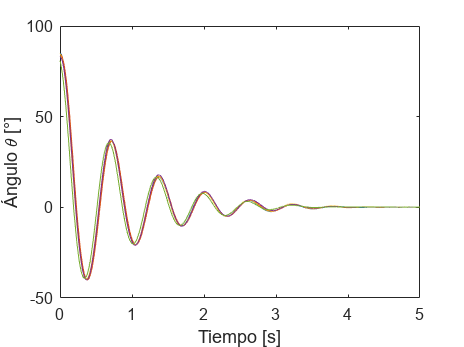

% Se cargan los datos obtenidos experimentalmente
load("FrictionCoef.mat")

figure()
plot(t1f, y1f);
hold on
plot(t2f, y2f);
plot(t3f, y3f);
plot(t4f, y4f);
plot(t5f, y5f);
xlim([0,5])
xlabel('Tiempo [s]')
ylabel('Ángulo \theta [°]')
hold off

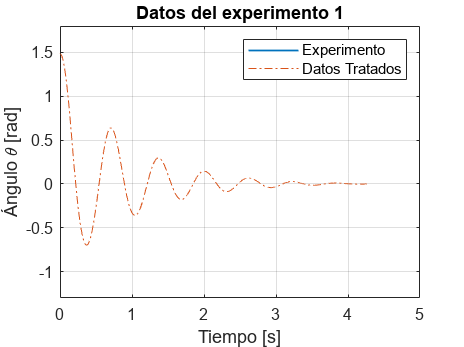

%Comparativa Datos obtenidos vs tratados
figure()
plot(t1,y1*pi/180,"LineWidth",1);
hold on
plot(t1f,y1f*pi/180,"-.");
hold off
title('Datos del experimento 1')
xlim([0,5])
ylim([-1.3,1.8])
xlabel('Tiempo [s]')
ylabel('Ángulo \theta [rad]')
grid("on")
legend('Experimento', 'Datos Tratados')

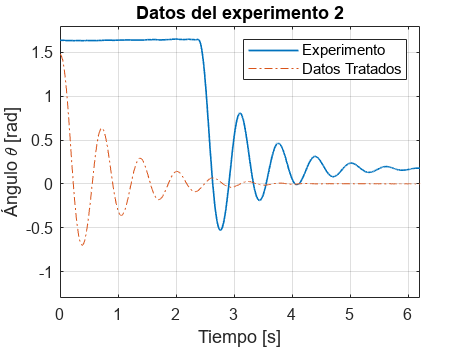


%Comparativa Datos obtenidos vs tratados
figure()
plot(t2,y2*pi/180,"LineWidth",1);
hold on
plot(t2f,y2f*pi/180,"-.");
hold off
title('Datos del experimento 2')
xlim([0,6.2])
ylim([-1.3,1.8])
xlabel('Tiempo [s]')
ylabel('Ángulo \theta [rad]')
grid("on")
legend('Experimento', 'Datos Tratados')

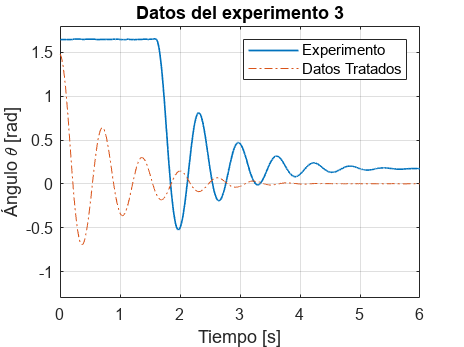


%Comparativa Datos obtenidos vs tratados
figure()
plot(t3,y3*pi/180,"LineWidth",1);
hold on
plot(t3f,y3f*pi/180,"-.");
hold off
title('Datos del experimento 3')
xlim([0,6])
ylim([-1.3,1.8])
xlabel('Tiempo [s]')
ylabel('Ángulo \theta [rad]')
grid("on")
legend('Experimento', 'Datos Tratados')

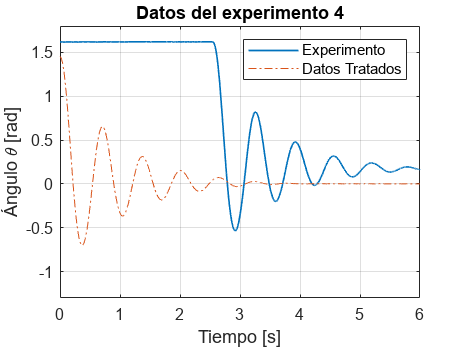


%Comparativa Datos obtenidos vs tratados
figure()
plot(t4,y4*pi/180,"LineWidth",1);
hold on
plot(t4f,y4f*pi/180,"-.");
hold off
title('Datos del experimento 4')
xlim([0,6])
ylim([-1.3,1.8])
xlabel('Tiempo [s]')
ylabel('Ángulo \theta [rad]')
grid("on")
legend('Experimento', 'Datos Tratados')

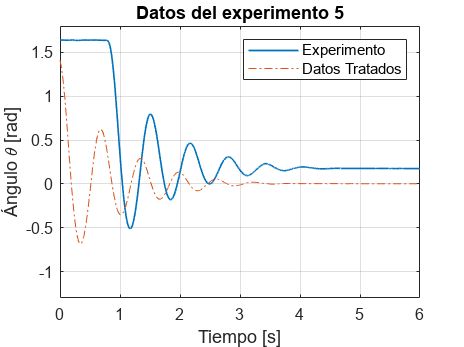


%Comparativa Datos obtenidos vs tratados
figure()
plot(t5,y5*pi/180,"LineWidth",1);
hold on
plot(t5f,y5f*pi/180,"-.");
hold off
title('Datos del experimento 5')
xlim([0,6])
ylim([-1.3,1.8])
xlabel('Tiempo [s]')
ylabel('Ángulo \theta [rad]')
grid("on")
legend('Experimento', 'Datos Tratados')

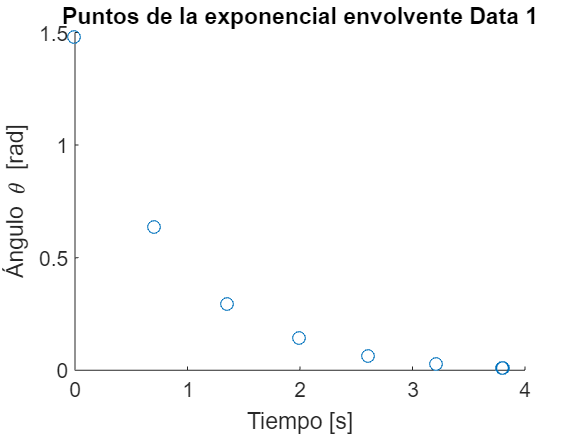

%Transformación a radianes
y1f = y1f*pi/180;
y2f = y2f*pi/180;
y3f = y3f*pi/180;
y4f = y4f*pi/180;
y5f = y5f*pi/180;

%Se encuentran los máximos y mínimos locales de la función teniendo en
%cuenta que no almacenará el primer valor de la función por lo que debe ser
%añadido

[pks1p,locs1p] = findpeaks(y1f,t1f);
[pks1n,locs1n] = findpeaks(-y1f,t1f);
pks1 = [y1f(1,1); pks1p];
locs1 = [t1f(1,1); locs1p];


%Se gráfican los picos
figure()
scatter(locs1,pks1);
title('Puntos de la exponencial envolvente Data 1')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

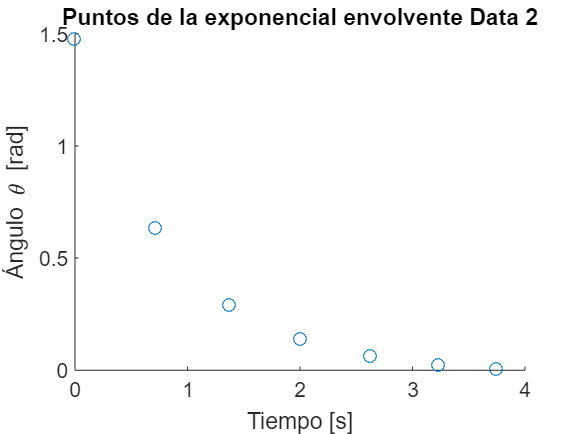


%Se encuentran los máximos y mínimos locales de la función teniendo en
%cuenta que no almacenará el primer valor de la función por lo que debe ser
%añadido

[pks2p,locs2p] = findpeaks(y2f,t2f);
[pks2n,locs2n] = findpeaks(-y2f,t2f);
pks2 = [y2f(1,1); pks2p];
locs2 = [t2f(1,1); locs2p];

%Se gráfican los picos
figure()
scatter(locs2,pks2);
title('Puntos de la exponencial envolvente Data 2')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

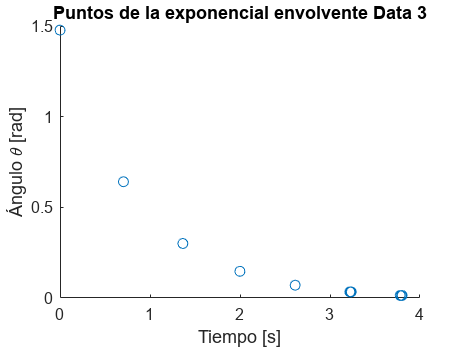



%Se encuentran los máximos y mínimos locales de la función teniendo en
%cuenta que no almacenará el primer valor de la función por lo que debe ser
%añadido

[pks3p,locs3p] = findpeaks(y3f,t3f);
[pks3n,locs3n] = findpeaks(-y3f,t3f);
pks3 = [y3f(1,1); pks3p];
locs3 = [t3f(1,1); locs3p];

%Se gráfican los picos
figure()
scatter(locs3,pks3);
title('Puntos de la exponencial envolvente Data 3')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

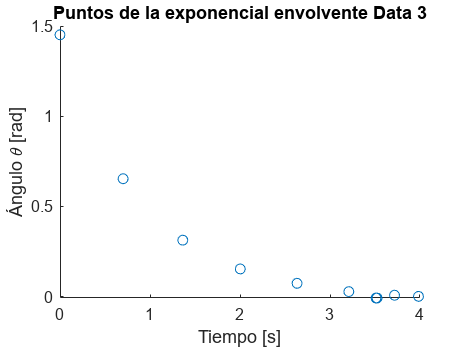


%Se encuentran los máximos y mínimos locales de la función teniendo en
%cuenta que no almacenará el primer valor de la función por lo que debe ser
%añadido

[pks4p,locs4p] = findpeaks(y4f,t4f);
[pks4n,locs4n] = findpeaks(-y4f,t4f);
pks4 = [y4f(1,1); pks4p];
locs4 = [t4f(1,1); locs4p];

%Se gráfican los picos
figure()
scatter(locs4,pks4);
title('Puntos de la exponencial envolvente Data 3')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

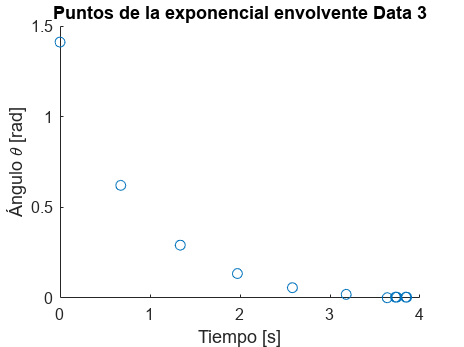



%Se encuentran los máximos y mínimos locales de la función teniendo en
%cuenta que no almacenará el primer valor de la función por lo que debe ser
%añadido

[pks5p,locs5p] = findpeaks(y5f,t5f);
[pks5n,locs5n] = findpeaks(-y5f,t5f);
pks5 = [y5f(1,1); pks5p];
locs5 = [t5f(1,1); locs5p];

%Se gráfican los picos
figure()
scatter(locs5,pks5);
title('Puntos de la exponencial envolvente Data 3')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

%Se encuentran las gráficas de las envolventes
envolvente1 = @(t) ((y1f(1,1))*exp(-1.13*t))

envolvente1 = function_handle with value:
    @(t)((y1f(1,1))*exp(-1.13*t))


envolvente2 = @(t) ((y2f(1,1))*exp(-1.15*t))

envolvente2 = function_handle with value:
    @(t)((y2f(1,1))*exp(-1.15*t))


envolvente3 = @(t) ((y3f(1,1))*exp(-1.14*t))

envolvente3 = function_handle with value:
    @(t)((y3f(1,1))*exp(-1.14*t))


envolvente4 = @(t) ((y4f(1,1))*exp(-1.13*t))

envolvente4 = function_handle with value:
    @(t)((y4f(1,1))*exp(-1.13*t))


envolvente5 = @(t) ((y5f(1,1))*exp(-1.15*t))

envolvente5 = function_handle with value:
    @(t)((y5f(1,1))*exp(-1.15*t))


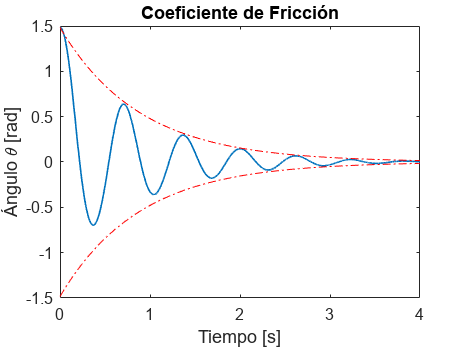

time = linspace(0,4,1000);

e1 = envolvente1(time);
e2 = envolvente2(time);
e3 = envolvente3(time);
e4 = envolvente4(time);
e5 = envolvente5(time);


% Se gráfican las funciones obtenidas
figure()
plot(t1f,y1f,'LineWidth',1);
hold on
plot(time,e1,'r-.');
plot(time,-e1,'r-.');
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

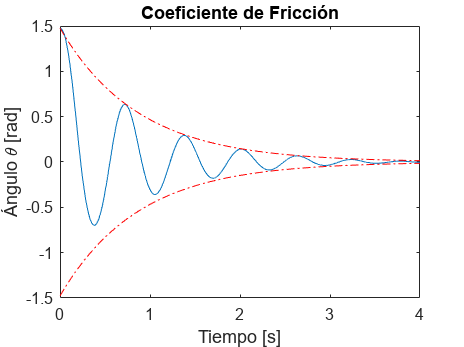


figure()
plot(t2f,y2f);
hold on
plot(time,e2,'r-.');
plot(time,-e2,'r-.');
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

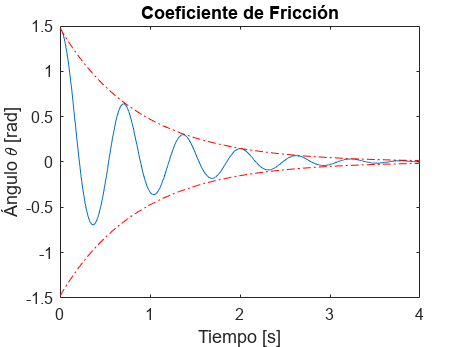


figure()
plot(t3f,y3f);
hold on
plot(time,e3,'r-.');
plot(time,-e3,'r-.');
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

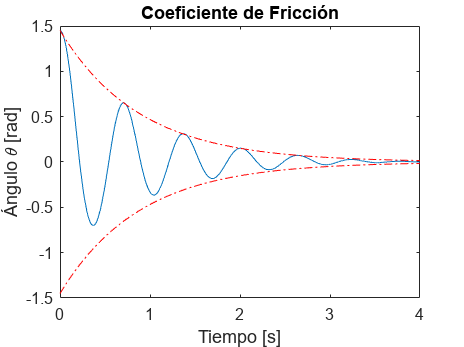


figure()
plot(t4f,y4f);
hold on
plot(time,e4,'r-.');
plot(time,-e4,'r-.');
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

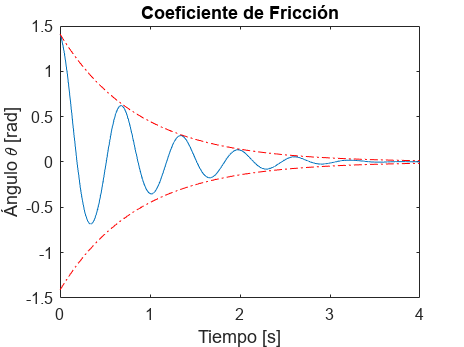



figure()
plot(t5f,y5f);
hold on
plot(time,e5,'r-.');
plot(time,-e5,'r-.');
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')